% Read Data from Excel
rawTable = readtable('Spacecraft_spin_module_frequency_response_data.xlsx','Sheet','Sheet1');

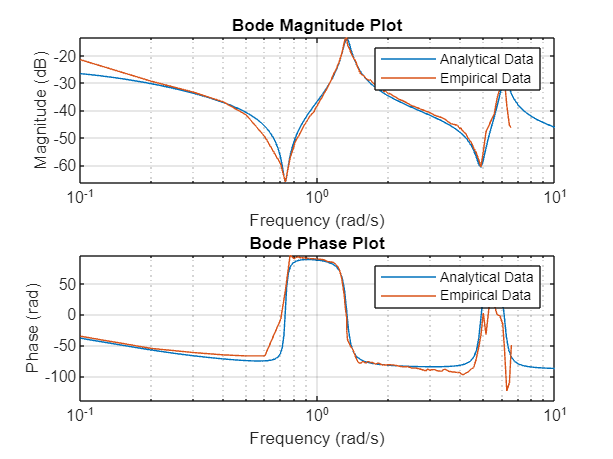

freq_data = rawTable.Frequency_Hz_;
mag_data = rawTable.Magnitude__rad_sec__V_;
mag_data = 20*log10(mag_data);
phase_data = rawTable.Phase_rad_;
phase_data = phase_data*360/(2*pi);

% Curve Fitting Transfer function
wn1 = 0.7323;
mag1 = 29.7268;
zeta1 = (10^(-mag1/20))/2;
wn2 = 1.32844;
mag2 = 24.2747;
zeta2 = (10^(-mag2/20))/2;
wn3 = 4.88315;
mag3 = 24.1018;
zeta3 = (10^(-mag3/20))/2;
wn4 = 6.13774;
mag4 = 24.1018;
zeta4 = (10^(-mag4/20))/2;

b1 = 2*zeta1*wn1;
c1 = wn1^2;
d1 = 2*zeta3*wn3;
e1 = wn3^2;
a = 10^-0.9;
b = 2*zeta2*wn2;
c = wn2^2;
d = 2*zeta4*wn4;
e = wn4^2;


K = 10^(-28.034/20);
H = tf(K*[1 b1+d1 e1+(b1*d1)+c1 (b1*e1)+(c1*d1) c1*e1],[1 (d+b+a) (e+((b+a)*d)+c+(a*b)) (((b+a)*e)+((c+(a*b))*d)+(a*c)) (((c+(a*b))*e)+(a*c*d)) a*c*e]);
[mag, phase, freq] = bode(H);

figure;
subplot(2,1,1);
semilogx(freq, 20*log10(squeeze(mag)));
xlabel('Frequency (rad/s)');
ylabel('Magnitude (dB)');
title('Bode Magnitude Plot');
grid on;
hold on;
plot(freq_data,mag_data);
legend('Analytical Data', 'Empirical Data');
xlim([0.1 10]);
hold off

subplot(2,1,2);
semilogx(freq, squeeze(phase));
xlabel('Frequency (rad/s)');
ylabel('Phase (rad)');
title('Bode Phase Plot');
axis([0 12 -140 96]);
grid on;
hold on;
plot(freq_data,phase_data);
legend('Analytical Data', 'Empirical Data');
axis([0.1 10 -140 96]);